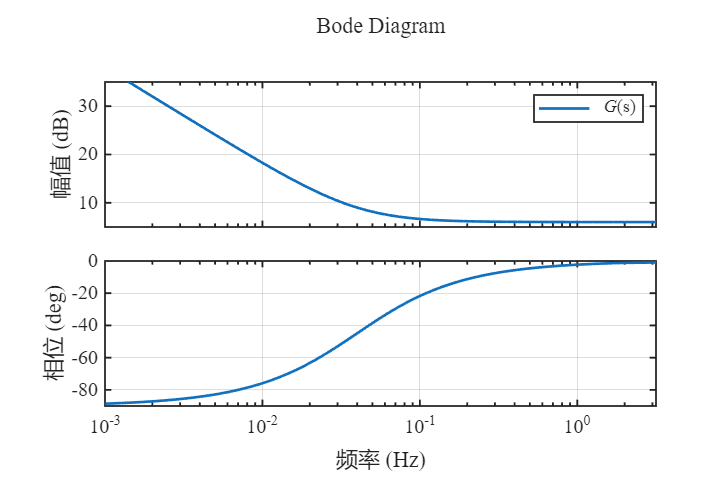

%% --------- "风格1"绘制 Bode：G(s)=(2s+0.5)/s ----------
clear; clc; close all;

% 1) 传递函数
num = [2 0.5];   % 2s + 0.5
den = [1 0];     % s
Gs  = tf(num, den);

%% 2) "风格1"全局绘图风格（中文宋体 + 英文/符号 Times New Roman，tex 混排）
set(groot, 'defaultFigureColor', 'w');

set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultTextFontName', 'Times New Roman');

set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultAxesLineWidth', 1.1);
set(groot, 'defaultLineLineWidth', 1.6);
set(groot, 'defaultAxesBox', 'on');
set(groot, 'defaultAxesTickDir', 'out');

set(groot, 'defaultAxesTickLabelInterpreter', 'tex');
set(groot, 'defaultTextInterpreter', 'tex');
set(groot, 'defaultLegendInterpreter', 'tex');

% 颜色（风格1）
C1 = [0.00, 0.45, 0.74];

%% 3) Bode 绘图（风格1排版与细节）
fig = figure('Units','centimeters','Position',[3 3 18 12]);

% 用 bodeplot 便于精细控制样式
h = bodeplot(Gs);
grid on;

% 线条颜色/线宽（对 bodeplot 句柄进行设置）
setoptions(h, 'FreqUnits','Hz');   % 如不想改单位可删掉这一行
setoptions(h, 'Grid','on');

% 取出 bodeplot 内部的两张坐标轴（幅频+相频），统一风格1网格透明度等
ax = findall(fig, 'Type', 'axes');
set(ax, 'Layer','top');            % 网格在下、曲线在上
for k = 1:numel(ax)
    ax(k).GridAlpha      = 0.15;
    ax(k).MinorGridAlpha = 0.08;
end

% bodeplot 的曲线对象设色（通常幅频、相频各一条同色）
ln = findall(fig, 'Type', 'line');
set(ln, 'Color', C1, 'LineWidth', 1.6);

% 标题（中文宋体 + 英文 Times New Roman，tex 混排）
% title('\fontname{SimSun}传递函数\fontname{Times New Roman}  G(s) = (2s+0.5)/s  \fontname{SimSun}的伯德图');

% 图例（风格1：边框、白底、Times New Roman）
leg = legend({'{\it G}(s)'}, 'Location','northeast');
set(leg, 'FontName','Times New Roman', 'FontSize', 11, ...
    'Box','on', 'EdgeColor',[0.2 0.2 0.2], 'LineWidth', 0.8, ...
    'Color','white', 'TextColor','black', 'ItemTokenSize',[14 10]);

%% 4) 导出（风格1）
% exportgraphics(fig, 'Bode_Gs.pdf', 'ContentType','vector');
print(fig, 'Bode_Gs_风格1', '-dpng', '-r600');